## **PL03 Variáveis e Distribuições Aleatórias**

## **3.1 Exercícios Suplementares**

**Brinquedo composto por ****2 componentes****, produzidos separadamente e posteriormente montados. Caixas com ****n**** brinquedos cada. O brinquedo tem defeito se um dos componentes for defeituoso. Probabilidade de defeito para cada componente:**

                                                                        **p1 = 0.002**            **p2 = 0.005**

**O processo de montagem produz brinquedos com defeito (mesmo c/ nenhum componente defeituoso) com ****p = 0.01**

#### **Ex1. Considera o acontecimento**

**A - "Uma caixa de brinquedos tem pelo menos um brinquedo defeituoso"**

    a) Estimar por simulação a probabilidade do acontecimento A para n = 8

numExp = 1e4;
n = 8;
p1 = 0.002;
p2 = 0.005;
p3 = 0.01;
matrizCaixa = zeros(3,n);
casosFav = 0;
casosFav_b = 0;

for i = 1:numExp
    matrizCaixa(1,:) = rand(1,n) < p1;
    matrizCaixa(2,:) = rand(1,n) < p2;
    matrizCaixa(3,:) = rand(1,n) < p3;

    if sum(matrizCaixa(:)) >= 1
        casosFav = casosFav + 1;    % Acontecimento A (pelo menos um defeituoso numa caixa)
        casosFav_b = casosFav_b + sum(matrizCaixa(3,:));    % (b)
    end
end

prob_a = casosFav / numExp

prob_a = 0.1299

alinea_b = casosFav_b / casosFav    % numero médio de defeitos por montagem quando o acontecimento A ocorre

alinea_b = 0.5928

    b) Estimar o número médio (por simulação) de brinquedos defeituosos apenas do processo de montagem quando ocorre o acontecimento A

(feito acima)

#### **Ex2. Considera o acontecimento**

**B - "Uma caixa de brinquedos não tem brinquedos com defeitos"**

    a) Estimar (por simulação) a probabilidade do acontecimento B quando n = 8 brinquedos.

numExp = 1e4;
n = 8;
p1 = 0.002;
p2 = 0.005;
p3 = 0.01;
matrizCaixa = zeros(3,n);
casosFav = 0;

for i = 1:numExp
    matrizCaixa(1,:) = rand(1,n) < p1;
    matrizCaixa(2,:) = rand(1,n) < p2;
    matrizCaixa(3,:) = rand(1,n) < p3;

    if sum(matrizCaixa(:)) == 0
        casosFav = casosFav + 1;    % Acontecimento B (nenhum brinquedo defeituoso na caixa)
    end
end

prob_a = casosFav / numExp

prob_a = 0.8749

    b) Calcular a probabiliadade de a) teóricamente.

prob_b = ((1-p1)*(1-p2)*(1-p3))^8

prob_b = 0.8724

    c) Simulações necessárias para criar um plot da probabilidade do acontecimento B em função do tamanho da caixa, n (todos os valores de 2 a 20).

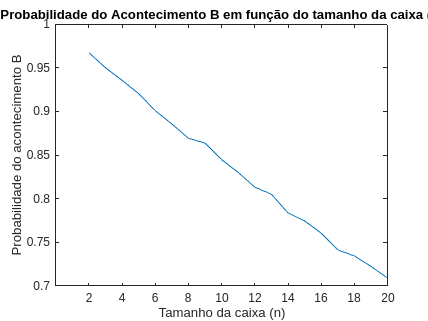

numExp = 1e4;
n = 2:1:20;
p1 = 0.002;
p2 = 0.005;
p3 = 0.01;
vetorCasosFav = zeros(1,length(n));

for size = 1:length(n)
    matrizCaixa = zeros(3,n(size));
    casosFav = 0;
    for i = 1:numExp
        matrizCaixa(1,:) = rand(1,n(size)) < p1;
        matrizCaixa(2,:) = rand(1,n(size)) < p2;
        matrizCaixa(3,:) = rand(1,n(size)) < p3;

        if sum(matrizCaixa(:)) == 0
            casosFav = casosFav + 1;  % Acontecimento B (nenhum brinquedo defeituoso)
        end
    end
    vetorCasosFav(size) = casosFav;  % casos favoraveis para o n atual
end

vetorProb = vetorCasosFav ./ numExp;  % probabilidade do acontecimento B para cada n

plot(n,vetorProb);
title('Probabilidade do Acontecimento B em função do tamanho da caixa (n)');
xlabel('Tamanho da caixa (n)');
ylabel('Probabilidade do acontecimento B')
xticks([2:2:20]);

    d) Capacidade máxima da caixa para garantir que a probabilidade do acontecimento B é de pelo menos 0.9.

**R: **De acordo com a análise do gráfico, a capacidade máxima da caixa para garantir que a probabilidade do acontecimento B é pelo menos 0.9 é n = 6. (eventualmente algum resultado da simulação terá a imagem de n = 6 inferior, mas na grande maioria dos casos é superior.)

#### **Ex3. Considera a variável aleatória X - número de brinquedos defeituosos numa caixa.**

    a) Estimar por simulação a função massa de probabilidade px(x) de X quando n = 8 e fazer o seu stem.

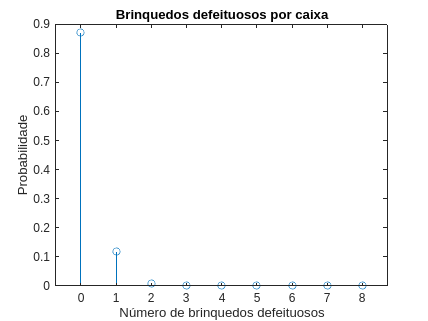

numExp = 1e4;
n = 8;
p1 = 0.002;
p2 = 0.005;
p3 = 0.01;
matrizCaixa = zeros(3,n);

X = 0:1:8;
vetorNumDefeituosos = zeros(1,length(X));

for i = 1:numExp
    matrizCaixa(1,:) = rand(1,n) < p1;
    matrizCaixa(2,:) = rand(1,n) < p2;
    matrizCaixa(3,:) = rand(1,n) < p3;
    numDefeituosos = sum(matrizCaixa(:));
    vetorNumDefeituosos(numDefeituosos + 1) = vetorNumDefeituosos(numDefeituosos + 1) + 1;
end

vetorProb = vetorNumDefeituosos/numExp;

stem(X,vetorProb);
title('Brinquedos defeituosos por caixa');
xlabel('Número de brinquedos defeituosos');
ylabel('Probabilidade');

A probabilidade de ter 1 defeituoso na caixa vai de acordo com o 2. a).

    b) Com base em px(x), calcular a probabilidade de X >= 2. O que conclui?

probAcumul = 0;

for i = 3:length(X)     % i = 3 -> X = 2
    probAcumul = probAcumul + vetorProb(i);
end

disp(['A probabilidade de X >= 2 é ',num2str(probAcumul)]);

A probabilidade de X >= 2 é 0.0083


    c) Com base em px(x), estimar valor esperado, variância e desvio padrão de X.

valorEsperado = 0;
for i = 1:length(X)
    valorEsperado = valorEsperado + X(i)*vetorProb(i);
end

valorEsperado_x2 = 0;
for i = 1:length(X)
    valorEsperado_x2 = valorEsperado_x2 + X(i)^2*vetorProb(i);
end
var = valorEsperado_x2 - valorEsperado^2;

desvio = sqrt(var);

disp(['Valor esperado: ', num2str(valorEsperado)]);

Valor esperado: 0.1355


disp(['Variância: ', num2str(var)]);

Variância: 0.13454


disp(['Desvio padrão: ', num2str(desvio)]);

Desvio padrão: 0.3668


    d) Repetir as últimas 3 alíneas mas para n = 16.

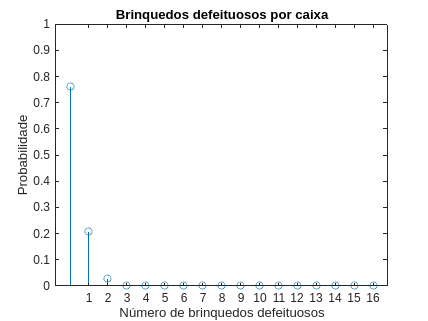

% a)
numExp = 1e4;
n = 16;
p1 = 0.002;
p2 = 0.005;
p3 = 0.01;
matrizCaixa = zeros(3,n);

X = 0:1:16;
vetorNumDefeituosos = zeros(1,length(X));

for i = 1:numExp
    matrizCaixa(1,:) = rand(1,n) < p1;
    matrizCaixa(2,:) = rand(1,n) < p2;
    matrizCaixa(3,:) = rand(1,n) < p3;
    numDefeituosos = sum(matrizCaixa(:));
    vetorNumDefeituosos(numDefeituosos + 1) = vetorNumDefeituosos(numDefeituosos + 1) + 1;
end

vetorProb = vetorNumDefeituosos/numExp;

stem(X,vetorProb);
title('Brinquedos defeituosos por caixa');
xlabel('Número de brinquedos defeituosos');
ylabel('Probabilidade');
ylim([0 1]);
xticks(1:1:16);


% b)
probAcumul = 0;

for i = 3:length(X)     % i = 3 -> X = 2
    probAcumul = probAcumul + vetorProb(i);
end

disp(['A probabilidade de X >= 2 é ',num2str(probAcumul)]);

A probabilidade de X >= 2 é 0.0321



% c)
valorEsperado = 0;
for i = 1:length(X)
    valorEsperado = valorEsperado + X(i)*vetorProb(i);
end

valorEsperado_x2 = 0;
for i = 1:length(X)
    valorEsperado_x2 = valorEsperado_x2 + X(i)^2*vetorProb(i);
end
var = valorEsperado_x2 - valorEsperado^2;

desvio = sqrt(var);

disp(['Valor esperado: ', num2str(valorEsperado)]);

Valor esperado: 0.2737


disp(['Variância: ', num2str(var)]);

Variância: 0.27639


disp(['Desvio padrão: ', num2str(desvio)]);

Desvio padrão: 0.52573


**R: **Comparando os valores obtidos para n=8 e para n=16 (de uma das simulações feitas)..:

**Probabilidade de X >= 2:**

    - Para n=8, P(X >= 2) = 0.0087

    - Para n=16, P(X >= 2) = 0.0308

Com o aumento do nº de brinquedos por caixa aumenta, a probabilidade de haver 2 ou mais brinquedos defeituosos aumenta, o que explica o aumento de P(X >= 2).

**Valor esperado:**

    - Para n=8, E(X) = 0.1358

    - Para n=16, E(X) = 0.280

Como o nº de brinquedos por caixa aumenta para o dobro, é de se esperar que o valor esperado de brinquedos defeituosos em cada caixa também duplique.

**Variância:**

    - Para n=8, Var(X) = 0.13796

    - Para n=16, Var(X) = 0.2752

Como o nº de brinquedos por caixa aumenta, o número de brinquedos defeituosos por caixa vai ter maior variabilidade, o que explica o aumento da variância (proporcionalmente ao valor esperado e número de brinquedos por caixa).

**Desvio padrão:**

    - Para n=8, σ(X) = 0.37143

    - Para n=16, σ(X) = 0.5246

O desvio padrão é a raiz quadrada da variância, logo também irá aumentar.

Por fim, pela análise de ambos os stems, podemos concluir que a probabilidade de existirem brinquedos defeituosos nas caixas aumenta quanto maior for o nº de brinquedos por caixa. Justifica por exemplo, o facto de a probabilidade de existirem 0 defeituosos com n = 16 ser menor que para n = 8.

#### **Ex4. n = 20, garantindo que a probabilidade de uma caixa comercializada não tenha brinquedos defeituosos seja pelo menos a 0.9. Para isso, o processo de montagem foi melhorado pelo que a probabilidade de originar um brinquedo defeituoso passou a ser 0.001.**

**** p3 = 0.001**

**Foi ainda implementado um processo de garantia de qualidade:**

**    - De cada caixa são selecionados m brinquedos (1 <= m < 20), aleatóriamente, para teste. Se existir algum defeituoso, essa caixa não é comercializada.**

    a) Estimar (simulação) a probabilidade de uma caixa ser comercializada quando o processo de garantia é implementado com m = 1

numExp = 1e4;
n = 20;
p1 = 0.002;
p2 = 0.005;
p3 = 0.001;
matrizCaixa = zeros(3,n);
m = 1;
caixasComerc = 0;
caixasComercDefeit = 0;
caixasDefeituosas = 0;

for i = 1:numExp
    matrizCaixa(1,:) = rand(1,n) < p1;
    matrizCaixa(2,:) = rand(1,n) < p2;
    matrizCaixa(3,:) = rand(1,n) < p3;
    vetorBrinq = sum(matrizCaixa);
    sel = randperm(n,m);    % seleciona um brinquedo aleatório
    
    if vetorBrinq(sel) == 0
        caixasComerc = caixasComerc + 1;
        if sum(matrizCaixa(:)) >= 1
            caixasComercDefeit = caixasComercDefeit + 1;
        end
    end

    if sum(matrizCaixa(:)) >= 1
        caixasDefeituosas = caixasDefeituosas + 1;
    end
end

prob_a = caixasComerc/numExp;        % alinea a
prob_caixasDefeituosas = caixasDefeituosas/numExp;       % num de caixas defeit produzidas no total
prob_caixasNaoDefeituosasComercializadas = (caixasComerc - caixasComercDefeit)/caixasComerc;

disp(['Prob da caixa ser comercializada: ', num2str(prob_a)]);

Prob da caixa ser comercializada: 0.9919


disp(['Prob das caixas terem brinquedos defeituosos (total): ', num2str(prob_caixasDefeituosas)]);

Prob das caixas terem brinquedos defeituosos (total): 0.1451


disp(['Prob das caixas comercializadas não serem defeituosas: ', num2str(prob_caixasNaoDefeituosasComercializadas)]);

Prob das caixas comercializadas não serem defeituosas: 0.86188


**R: **Com m = 1, cerca de 99% de todas as caixas produzidas são comercializadas, mas isso não quer dizer que a taxa de caixas sem brinquedos defeituosos comercializada tenha uma probabilidade de 0,9.

Adicionando algumas coisas extra, pode se verificar que das caixas comercializadas, apenas 0.85 (+ -) não contém defeitos, que ainda está longe de 0.9.

    b) Estimar m mínimo para atingir o pretendido.

numExp = 1e4;
n = 20;
p1 = 0.002;
p2 = 0.005;
p3 = 0.001;
matrizCaixa = zeros(3,n);
vetorM = 1:1:19;

for j = 1:length(vetorM)
    caixasComerc = 0;
    caixasComercDefeit = 0;
    m = j;
    for i = 1:numExp
        matrizCaixa(1,:) = rand(1,n) < p1;
        matrizCaixa(2,:) = rand(1,n) < p2;
        matrizCaixa(3,:) = rand(1,n) < p3;
        vetorBrinq = sum(matrizCaixa);
        sel = randperm(n,m);    % seleciona m brinquedos para teste
        
        if all(vetorBrinq(sel) == 0)
            caixasComerc = caixasComerc + 1;
            if sum(matrizCaixa(:)) >= 1
                caixasComercDefeit = caixasComercDefeit + 1;
            end
        end
    end
    prob_caixasNaoDefeituosasComercializadas = (caixasComerc - caixasComercDefeit)/caixasComerc;

    if prob_caixasNaoDefeituosasComercializadas >= 0.9
        m_min = m;
        break
    end
end

disp(['Prob das caixas comercializadas não serem defeituosas: ', num2str(prob_caixasNaoDefeituosasComercializadas)]);

Prob das caixas comercializadas não serem defeituosas: 0.90667


disp(['m mínimo para garantir o objetivo pretendido: ', num2str(m_min)]);

m mínimo para garantir o objetivo pretendido: 7
